**포텐셜 함수와 중력장**

- **중력 포텐셜**: 중력장은 보존적인 힘의 장이며, 이로 인해 중력장에는 스칼라 포텐셜 함수, 즉 중력 포텐셜이 존재합니다. 

- 중력 포텐셜 $\Phi(\vec{r})$는 위치 벡터$\vec{r}$에서의 중력장에 의한 퍼텐셜 에너지를 나타냅니다.

- **중력장과 포텐셜의 관계**: 중력장은 중력 포텐셜의 그래디언트(gradient)로 표현됩니다. $\vec{g}(\vec{r}) = -\nabla \Phi(\vec{r})$여기서 $\vec{g}$는 중력장, $\nabla$는 벡터 미분 연산자(그래디언트)입니다.

- 중력장 $\vec{g}$�는 공간의 각 지점에서 중력의 세기와 방향을 나타냅니다.

- 포텐셜 함수 $\Phi(\vec{r})$는 공간의 각 지점에서 단위 질량이 가지는 퍼텐셜 에너지를 나타냅니다.

**중력 포텐셜의 계산**

- 한 점 질량 $M$에 의한 중력 포텐셜은 그 주변의 위치$\vec{r}$에서 다음과 같이 주어집니다: $|r⃗|\Phi(\vec{r}) = -\frac{GM}{|\vec{r}|}$�여기서 $G$는 중력 상수, $|\vec{r}|$는 원점에서 위치 $\vec{r}$까지의 거리입니다.

- 이 포텐셜로부터 중력장을 계산하려면, 그래디언트 연산을 사용합니다: 


$$\vec{g}(\vec{r}) = -\nabla \Phi(\vec{r}) = -\nabla \left( -\frac{GM}{|\vec{r}|} \right)$$


- 결과적으로 이는:


$$\vec{g}(\vec{r}) = -\frac{GM}{|\vec{r}|^3} \vec{r}$$


- 여기서 $\vec{g}(\vec{r})$는 위치 $\vec{r}$에서의 중력장 벡터를 나타냅니다.

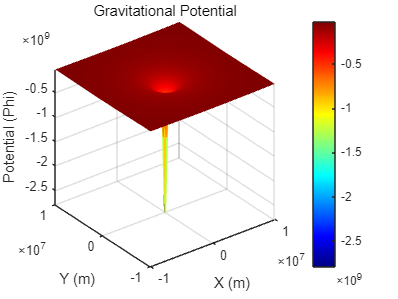

% 중력장 계산을 위한 MATLAB 코드
% 1. 포텐셜 함수 계산

% 상수 정의
G = 6.67430e-11; % 중력 상수 (m^3 kg^-1 s^-2)
M = 5.972e24; % 지구의 질량 (kg)
r_max = 10e6; % 최대 거리 (m)

% 격자 생성
x = linspace(-r_max, r_max, 100);
y = linspace(-r_max, r_max, 100);
[X, Y] = meshgrid(x, y);
Z = sqrt(X.^2 + Y.^2); % 거리 계산

% 포텐셜 함수 계산
Phi = -G * M ./ Z; % Z가 0인 경우를 처리하지 않아도 MATLAB에서 자동 처리

% 2. 3D 시각화
figure;
surf(X, Y, Phi, 'EdgeColor', 'none');
colormap('jet'); % 컬러맵을 'jet'으로 변경
colorbar;
title('Gravitational Potential');
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Potential (Phi)');
axis tight;
view(3);

- **포텐셜 함수 계산**:

- 중력 상수 $G$와 지구의 질량 $M$을 사용하여 포텐셜 함수를 계산합니다.

- 위치 $(x,y)$에서의 거리를 계산하고, 이를 통해 중력 포텐셜 $\Phi$를 계산합니다.

- MATLAB에서 `meshgrid`를 사용하여 2차원 격자를 생성하고, 각 격자점에서의 중력 포텐셜을 계산합니다.

- **3D 시각화**:

- `surf` 함수를 사용하여 포텐셜 함수를 3D 표면으로 시각화합니다.

- `colormap`과 `colorbar`를 사용하여 그래프의 색상을 지정하고 색상 막대를 추가합니다.

- `view(3)`를 사용하여 3차원으로 표시되도록 설정합니다.